**This is for analysis**

% % we need to get ground truth data

[truthFile, truthPath] = uigetfile('D:\p\m\DIC_Analysis\temp_results\*.mat','select the results for twin-grain boundary intersection');
load(fullfile(truthPath,truthFile),'struCell');
load('temp_results/optimum_identification.mat');

% (1) For those previously not twinned, maybe need a more strict criterion, and the true positives are
ind = (T.cTrueTwin==1)&(T.activePre==0);  % 

% For those twinned at post strain level, maybe a less strict criterion is OK, those true positives are:  
ind = (T.cTrueTwin==1)&(T.activePost==1);

% strain rank distribution, --> basically, not the lowest rank
disp('=====all========')

=====all========


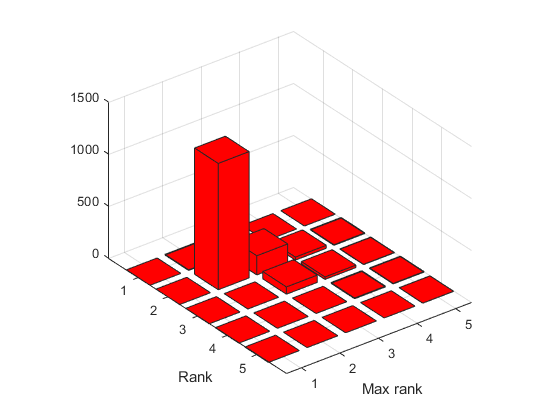

ind = (T.cTrueTwin==1);
t1 = T(ind,:);  % twinned
t2 = T(~ind,:); % non-twinned

xEdge = [0:5] - 0.5;
yEdge = [0:5] - 0.5;
[N1,xEdge,yEdge] = histcounts2(t1.cStrainRankMax, t1.cStrainRank, xEdge, yEdge);
[N2,xEdge,yEdge] = histcounts2(t2.cStrainRankMax, t2.cStrainRank, xEdge, yEdge);

figure; disableDefaultInteractivity(gca);
bar3(N1','r');
% set(gca,'ydir','normal');
xlabel('Max rank');
ylabel('Rank');

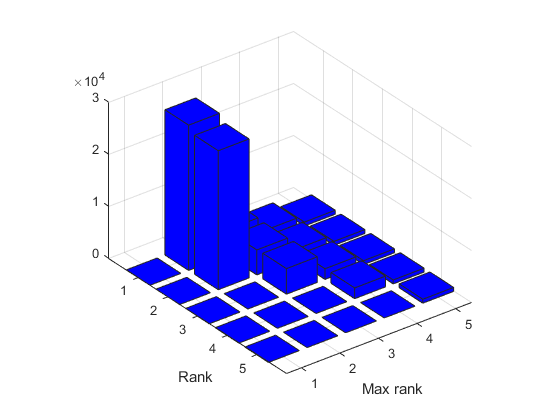


figure; disableDefaultInteractivity(gca);
bar3(N2','b');
% set(gca,'ydir','normal');
xlabel('Max rank');
ylabel('Rank');


tbl_1 = array2table(N1);
tbl_1.Properties.VariableNames = {'n1','n2','n3','n4','n5'};
tbl_2 = array2table(N2);
tbl_2.Properties.VariableNames = {'n1','n2','n3','n4','n5'};
display(tbl_1);

tbl_1 = 5×5 table
    n1     n2     n3    n4    n5
    __    ____    __    __    __
    0        0     0    0     0 
    6     1213     0    0     0 
    0      184    70    0     0 
    0       29    24    7     0 
    0        6     3    5     1 

display(tbl_2);

tbl_2 = 5×5 table
     n1       n2       n3      n4     n5 
    _____    _____    ____    ____    ___
        0        0       0       0      0
    27906    26699       0       0      0
     4986     4802    4916       0      0
     2076     2047    2052    2069      0
      762      756     759     757    761

% Seems whether previously twinned or not, does not affect the rank distribution   
disp('======previously not twinned==========')

======previously not twinned==========


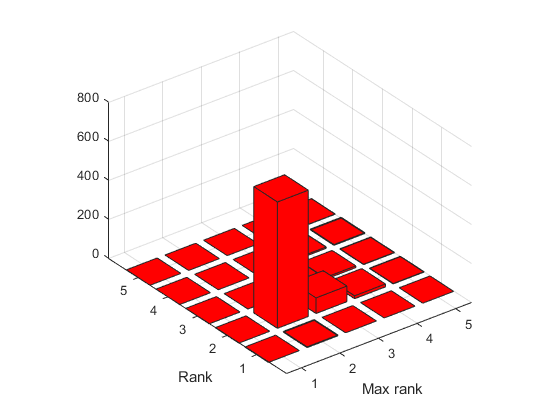

ind = (T.cTrueTwin==1)&(T.activePre==0);
t1 = T(ind,:);  % twinned, but previously not twinned
ind = (T.cTrueTwin==1)&(T.activePre==1);
t2 = T(ind,:);  % twinned, and previously twinned
ind = (T.cTrueTwin==0)&(T.activePre==0);
t3 = T(ind,:); % not twinned, and prevously not twinned

xEdge = [0:5] - 0.5;
yEdge = [0:5] - 0.5;
[N1,xEdge,yEdge] = histcounts2(t1.cStrainRankMax, t1.cStrainRank, xEdge, yEdge);
[N2,xEdge,yEdge] = histcounts2(t2.cStrainRankMax, t2.cStrainRank, xEdge, yEdge);
[N3,xEdge,yEdge] = histcounts2(t3.cStrainRankMax, t3.cStrainRank, xEdge, yEdge);

figure; 
bar3(N1','r');
set(gca,'ydir','normal');
xlabel('Max rank');
ylabel('Rank');

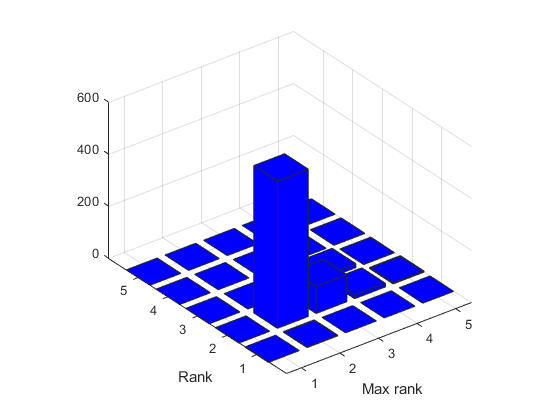


figure; 
bar3(N2','b');
set(gca,'ydir','normal');
xlabel('Max rank');
ylabel('Rank');

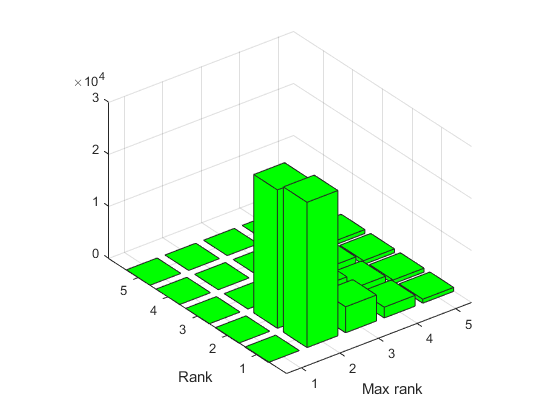


figure; 
bar3(N3','g');
set(gca,'ydir','normal');
xlabel('Max rank');
ylabel('Rank');



tbl_1 = array2table(N1);
tbl_1.Properties.VariableNames = {'n1','n2','n3','n4','n5'};
tbl_2 = array2table(N2);
tbl_2.Properties.VariableNames = {'n1','n2','n3','n4','n5'};
tbl_3 = array2table(N3);
tbl_3.Properties.VariableNames = {'n1','n2','n3','n4','n5'};
display(tbl_1);

tbl_1 = 5×5 table
    n1    n2     n3    n4    n5
    __    ___    __    __    __
    0       0     0    0     0 
    4     647     0    0     0 
    0      80    48    0     0 
    0      15     9    7     0 
    0       2     2    4     1 

display(tbl_2);

tbl_2 = 5×5 table
    n1    n2     n3    n4    n5
    __    ___    __    __    __
    0       0     0    0     0 
    2     566     0    0     0 
    0     104    22    0     0 
    0      14    15    0     0 
    0       4     1    1     0 

display(tbl_3);

tbl_3 = 5×5 table
     n1       n2       n3      n4     n5 
    _____    _____    ____    ____    ___
        0        0       0       0      0
    27906    26581       0       0      0
     4986     4778    4903       0      0
     2076     2045    2051    2069      0
      762      752     756     756    761

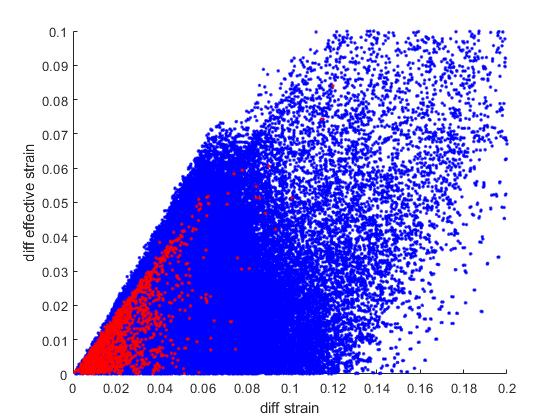

% diff in strain and in effective strain: value
ind = (T.cTrueTwin==1);
t1 = T(ind,:);  % twinned
t2 = T(~ind,:); % non-twinned

figure; disableDefaultInteractivity(gca); hold on;
plot(t2.dStrain,t2.dEffStrain,'.b');
plot(t1.dStrain,t1.dEffStrain,'.r');
set(gca,'xlim',[0 0.2],'ylim',[0 0.1]);
xlabel('diff strain');
ylabel('diff effective strain')

% Look at the distribution of: difference/ratio in strain/effective strain
C = colororder;
ind = (T.cStrainRank>0)&(T.cTrueTwin==1);   % high strain, and twinned 
t1 = T(ind,:);  
ind = (T.cStrainRank>0)&(T.cTrueTwin==0);   % high strain, and not twinned
t2 = T(ind,:); 

disp('Strain difference:');

Strain difference:


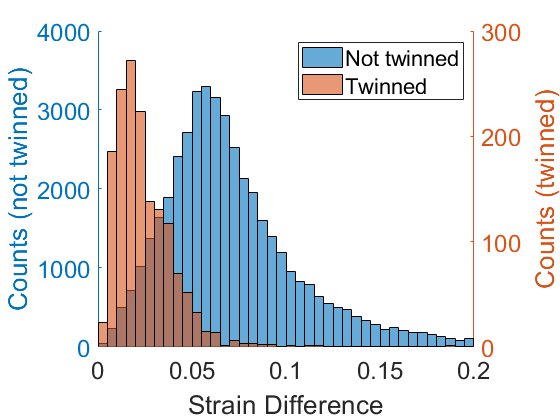

% --> Difference in strain, twinned & non-twinned
figure; disableDefaultInteractivity(gca); hold on;
xlabel('Strain Difference');
yyaxis left;
ylabel('Counts (not twinned)');
histogram(t2.dStrain, [0:0.005:0.2],'facecolor',C(1,:));%0.195,inf]);
set(gca,'ycolor',C(1,:),'xlim',[0,0.2],'fontsize',18);
yyaxis right;
ylabel('Counts (twinned)');
histogram(t1.dStrain, [0:0.005:0.2], 'facecolor',C(2,:));%0.195,inf]);
set(gca,'ycolor',C(2,:)); hold on;
legend('Not twinned', 'Twinned');

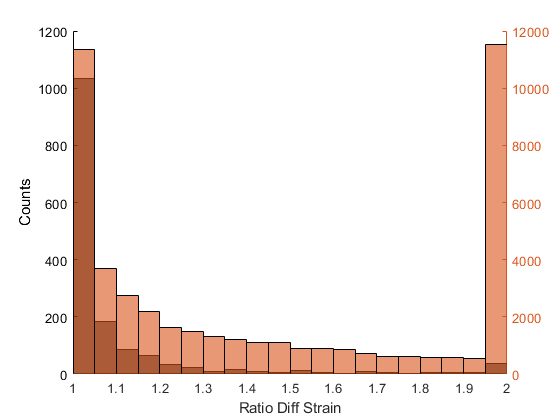

% title('Diff Strain');

% --> Ratio of cluster's diff in strain over min of them
figure; disableDefaultInteractivity(gca); hold on;
xlabel('Ratio Diff Strain');
ylabel('Counts');
histogram(t1.rStrain,[1:0.05:1.95,inf]);
yyaxis right;
histogram(t2.rStrain,[1:0.05:1.95,inf]);
set(gca,'xlim',[1 2])

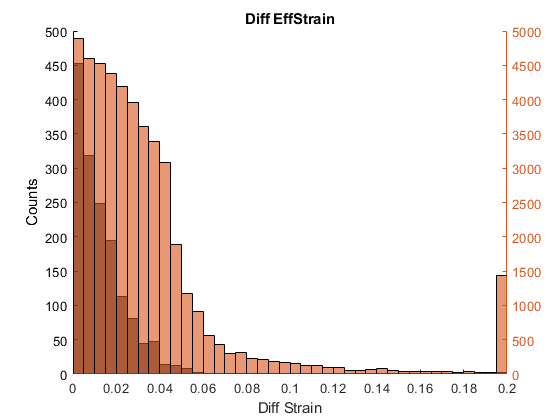


% --> Diff between cluster Effective Strain and that of twin
figure; disableDefaultInteractivity(gca); hold on;
xlabel('Diff Strain');
ylabel('Counts');
histogram(t1.dEffStrain, [0:0.005:0.195,inf]);
yyaxis right;
histogram(t2.dEffStrain, [0:0.005:0.195,inf]);
set(gca,'xlim',[0,0.2]);
title('Diff EffStrain');

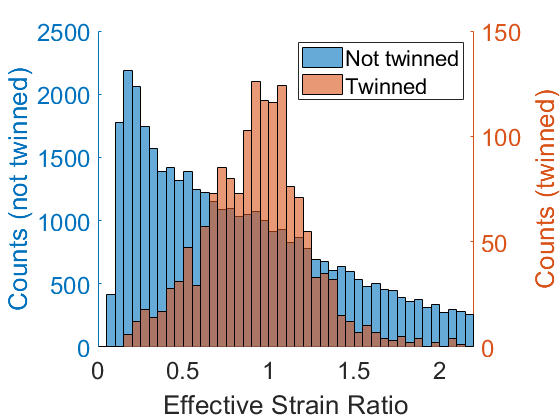


% --> Ratio of cluster effective strain over that of twin
figure; disableDefaultInteractivity(gca); hold on;
xlabel('Effective Strain Ratio');

yyaxis left;
ylabel('Counts (not twinned)');
histogram(t2.rEffStrain,[0:0.05:2.2], 'facecolor',C(1,:)); %1.95,inf]);
set(gca,'ycolor',C(1,:),'xlim',[0,2.2],'fontsize',18);
yyaxis right;
ylabel('Counts (twinned)');
histogram(t1.rEffStrain,[0:0.05:2.2], 'facecolor',C(2,:)); %1.95,inf]);
set(gca,'ycolor',C(2,:));
legend('Not twinned','Twinned');

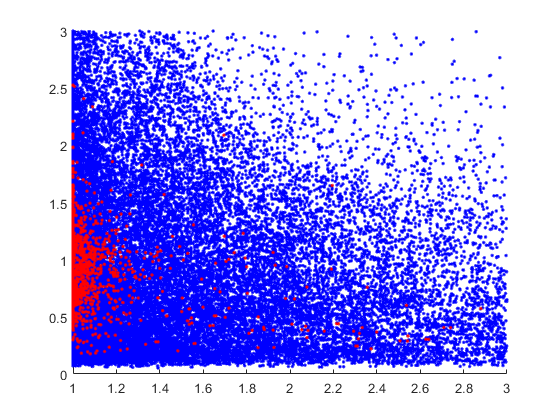

% title('Ratio cluster strain/twin strain');

% --> use scatter plot
figure; disableDefaultInteractivity(gca); hold on;
plot(t2.rStrain, t2.rEffStrain, '.b');
plot(t1.rStrain, t1.rEffStrain, '.r');
set(gca,'xlim',[1,3],'ylim',[0 3]);

% do the previou for different iEs ===> not effect
disp('====== strain criterion ============');

====== strain criterion ============


==== iE=2 ====


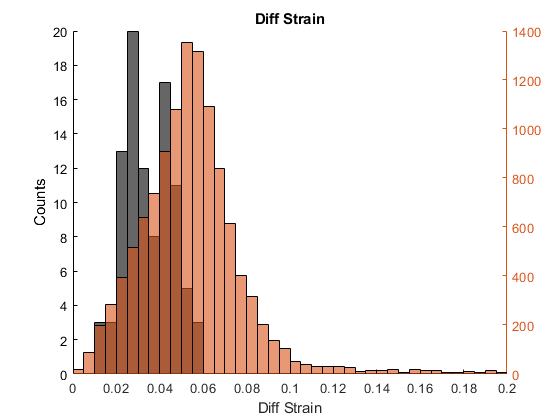

==== iE=3 ====


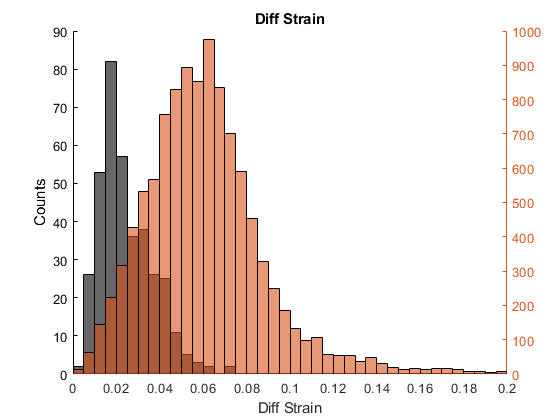

==== iE=4 ====


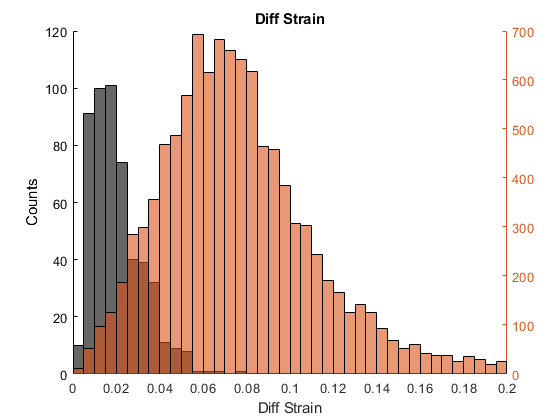

==== iE=5 ====


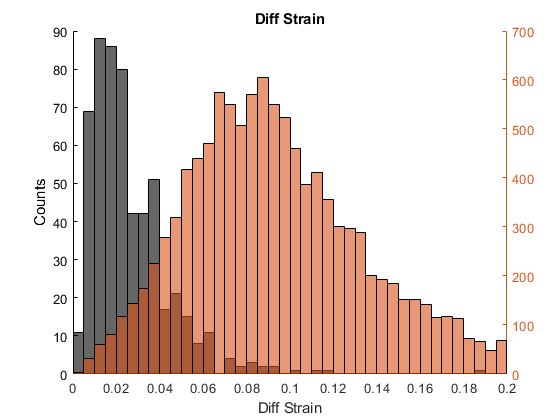

for iE = 2:5
    disp(['==== iE=',num2str(iE),' ====']);
    ind = (T.cStrainRank>0)&(T.cTrueTwin==1)&(T.iE==iE);   % high strain, and twinned
    t1 = T(ind,:);
    ind = (T.cStrainRank>0)&(T.cTrueTwin==0)&(T.iE==iE);   % high strain, and not twinned
    t2 = T(ind,:);
    
    % --> Difference in strain, twinned & non-twinned
    figure; disableDefaultInteractivity(gca); hold on;
    xlabel('Diff Strain');
    ylabel('Counts');
    histogram(t1.dStrain,[0:0.005:0.2]);
    yyaxis right;
    histogram(t2.dStrain,[0:0.005:0.2]);
    set(gca,'xlim',[0,0.2]);
    title('Diff Strain');
end

==== iE=2 ====


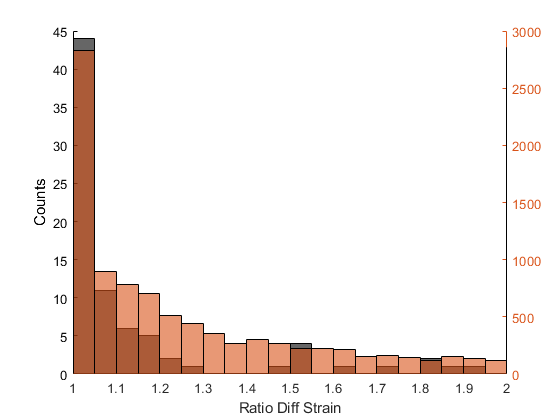

==== iE=3 ====


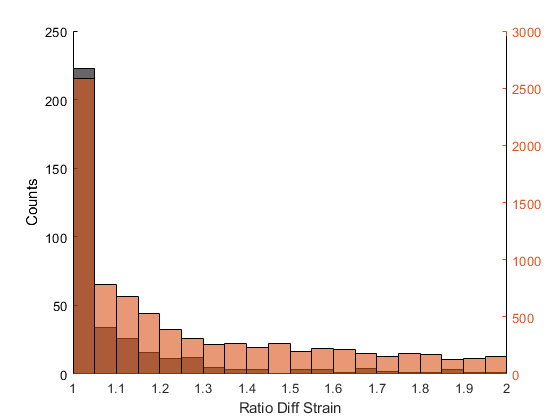

==== iE=4 ====


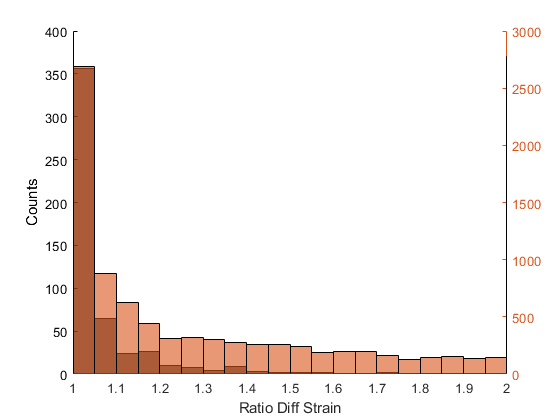

==== iE=5 ====


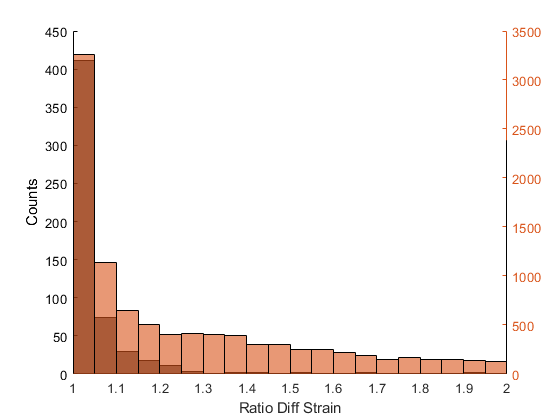


for iE = 2:5
    disp(['==== iE=',num2str(iE),' ====']);
    ind = (T.cStrainRank>0)&(T.cTrueTwin==1)&(T.iE==iE);   % high strain, and twinned
    t1 = T(ind,:);
    ind = (T.cStrainRank>0)&(T.cTrueTwin==0)&(T.iE==iE);   % high strain, and not twinned
    t2 = T(ind,:);

    % --> Ratio of cluster's diff in strain over min of them
    figure; disableDefaultInteractivity(gca); hold on;
    xlabel('Ratio Diff Strain');
    ylabel('Counts');
    histogram(t1.rStrain,[1:0.05:2,inf]);
    yyaxis right;
    histogram(t2.rStrain,[1:0.05:2,inf]);
    set(gca,'xlim',[1 2])
end

==== iE=2 ====


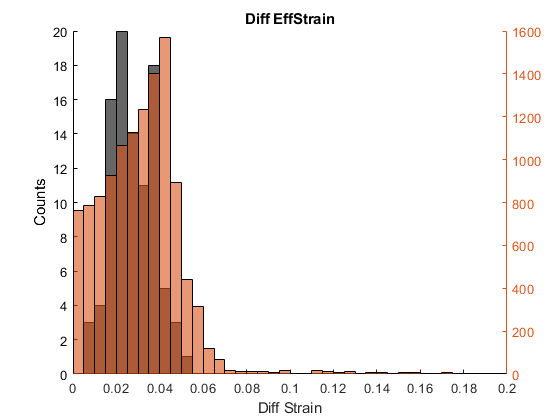

==== iE=3 ====


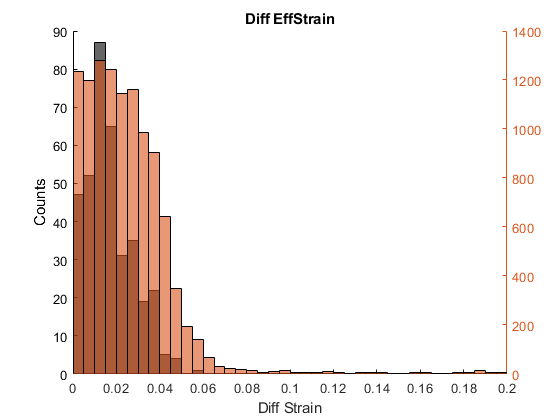

==== iE=4 ====


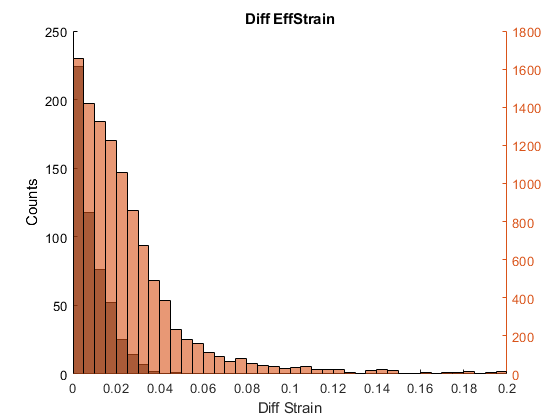

==== iE=5 ====


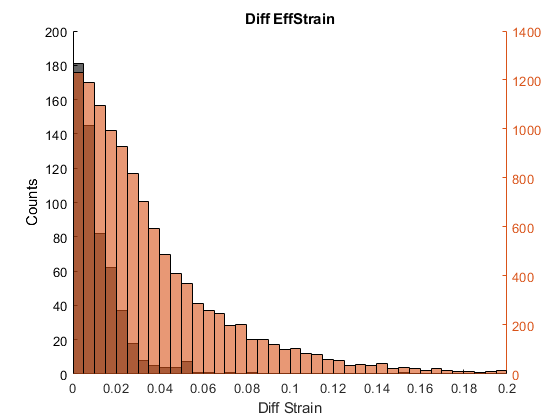


for iE = 2:5
    disp(['==== iE=',num2str(iE),' ====']);
    ind = (T.cStrainRank>0)&(T.cTrueTwin==1)&(T.iE==iE);   % high strain, and twinned
    t1 = T(ind,:);
    ind = (T.cStrainRank>0)&(T.cTrueTwin==0)&(T.iE==iE);   % high strain, and not twinned
    t2 = T(ind,:);

    % --> Diff between cluster Effective Strain and that of twin
    figure; disableDefaultInteractivity(gca); hold on;
    xlabel('Diff Strain');
    ylabel('Counts');
    histogram(t1.dEffStrain,[0:0.005:0.2]);
    yyaxis right;
    histogram(t2.dEffStrain,[0:0.005:0.2]);
    set(gca,'xlim',[0,0.2]);
    title('Diff EffStrain');
end

==== iE=2 ====


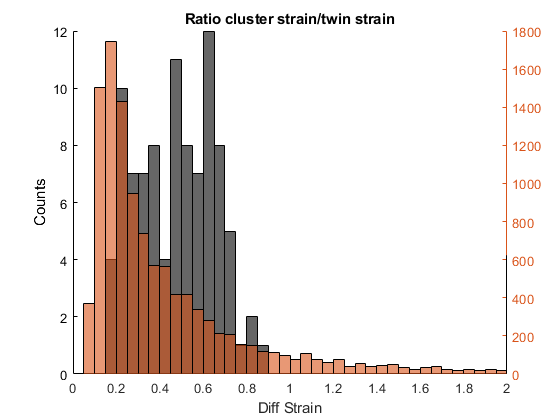

==== iE=3 ====


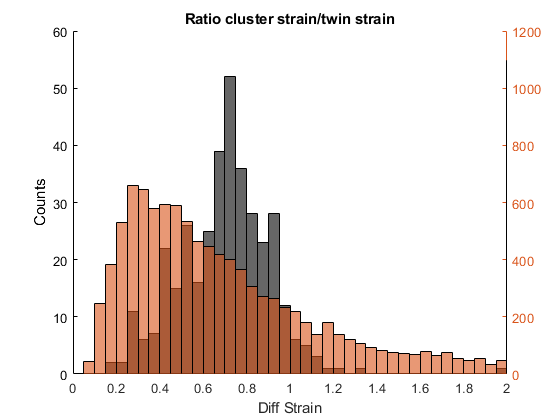

==== iE=4 ====


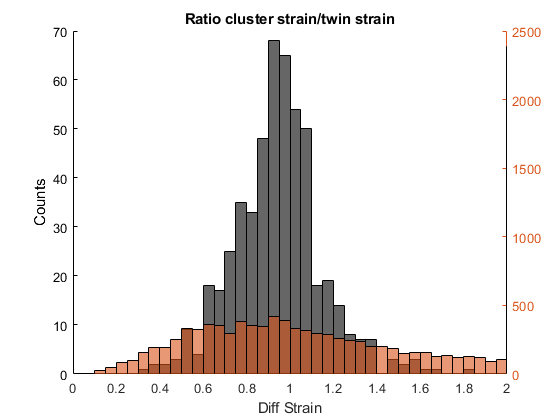

==== iE=5 ====


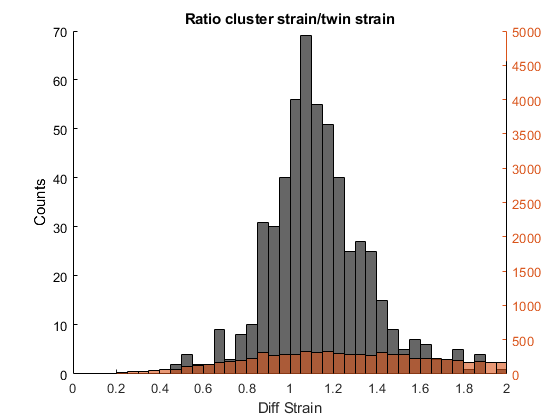


for iE = 2:5
    disp(['==== iE=',num2str(iE),' ====']);
    ind = (T.cStrainRank>0)&(T.cTrueTwin==1)&(T.iE==iE);   % high strain, and twinned
    t1 = T(ind,:);
    ind = (T.cStrainRank>0)&(T.cTrueTwin==0)&(T.iE==iE);   % high strain, and not twinned
    t2 = T(ind,:);
    
    % --> Ratio of cluster effective strain over that of twin
    figure; disableDefaultInteractivity(gca); hold on;
    xlabel('Diff Strain');
    ylabel('Counts');
    histogram(t1.rEffStrain,[0:0.05:2,inf]);
    yyaxis right;
    histogram(t2.rEffStrain,[0:0.05:2,inf]);
    set(gca,'xlim',[0,2]);
    title('Ratio cluster strain/twin strain');
end

==== iE=2 ====


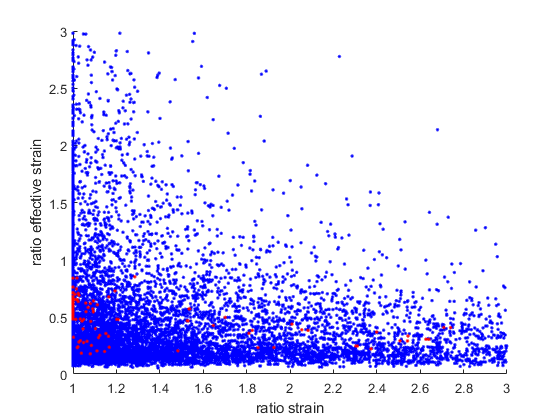

==== iE=3 ====


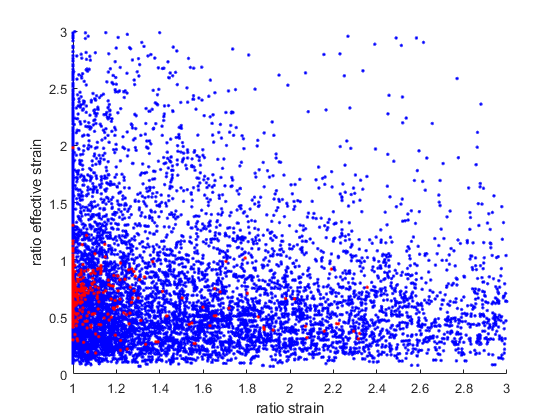

==== iE=4 ====


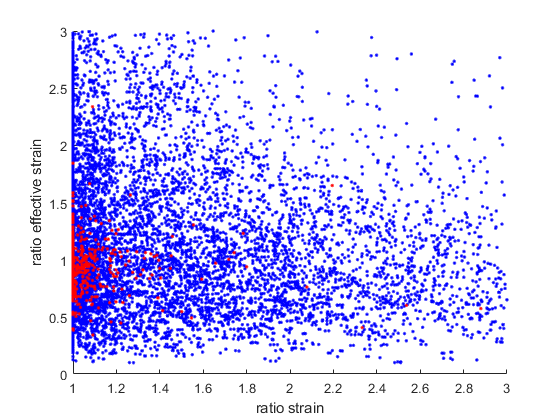

==== iE=5 ====


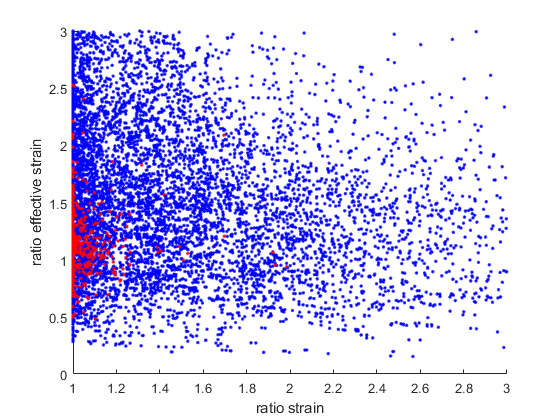


for iE = 2:5
    disp(['==== iE=',num2str(iE),' ====']);
    ind = (T.cStrainRank>0)&(T.cTrueTwin==1)&(T.iE==iE);   % high strain, and twinned
    t1 = T(ind,:);
    ind = (T.cStrainRank>0)&(T.cTrueTwin==0)&(T.iE==iE);   % high strain, and not twinned
    t2 = T(ind,:);

    % --> use scatter plot
    figure; disableDefaultInteractivity(gca); hold on;
    plot(t2.rStrain, t2.rEffStrain, '.b');
    plot(t1.rStrain, t1.rEffStrain, '.r');
    set(gca,'xlim',[1,3],'ylim',[0 3]);
    xlabel('ratio strain');
    ylabel('ratio effective strain');
    
end

disp('==== trace criterion ====');

==== trace criterion ====


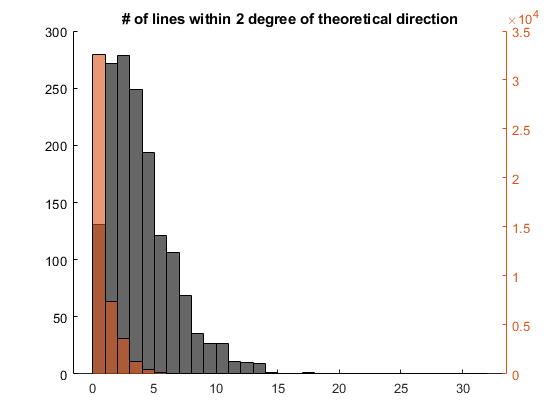

% Then, need to look at trace direction criterion.
% distribution: how many peaks (lines) are within 1,2,3,4,5 degrees of the theoretical trace direction   
% for twinned, and non twinned
 
ind = (T.cStrainRank>0)&(T.cTrueTwin==1);   % twinned
t1 = T(ind,:);
ind = (T.cStrainRank>0)&(T.cTrueTwin==0);   % not twinned
t2 = T(ind,:);
t1CS = cumsum([t1.d1, t1.d2, t1.d3, t1.d4, t1.d5],2);
t2CS = cumsum([t2.d1, t2.d2, t2.d3, t2.d4, t2.d5],2);

figure; hold on;
histogram(t1CS(:,2),0:32);
yyaxis right;
histogram(t2CS(:,2),0:32);
title('# of lines within 2 degree of theoretical direction');

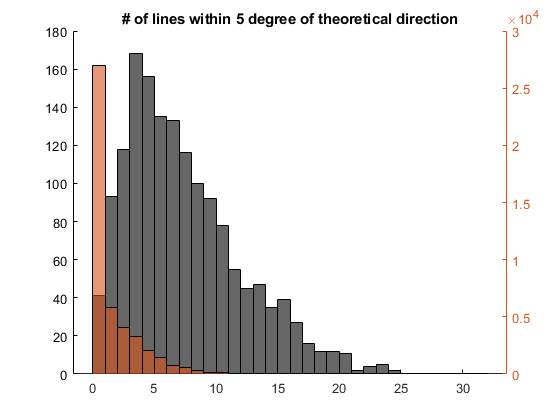

  
figure; hold on;
histogram(t1CS(:,5),0:32);
yyaxis right;
histogram(t2CS(:,5),0:32);
title('# of lines within 5 degree of theoretical direction');

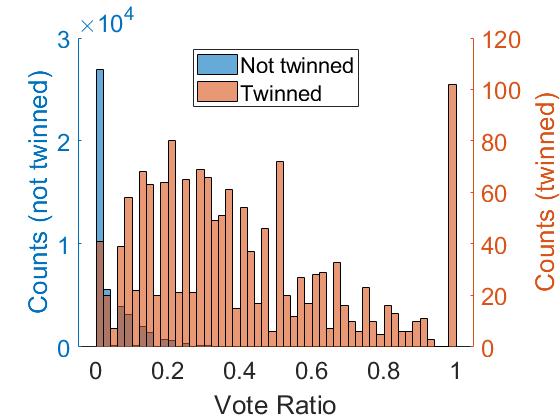



figure; hold on;
xlabel('Vote Ratio');
yyaxis left;
histogram(t2CS(:,5)./t2.nPeaks,50,'facecolor',C(1,:));
ylabel('Counts (not twinned)');
set(gca,'ycolor',C(1,:));
yyaxis right;
histogram(t1CS(:,5)./t1.nPeaks,50,'facecolor',C(2,:));
ylabel('Counts (twinned)');
set(gca,'ycolor',C(2,:));
legend('Not twinned','Twinned','location','north');
% title('# within 5d/ #Lines total');
set(gca,'fontsize',18);

disp('==== look at if active pre/post ====');

==== look at if active pre/post ====


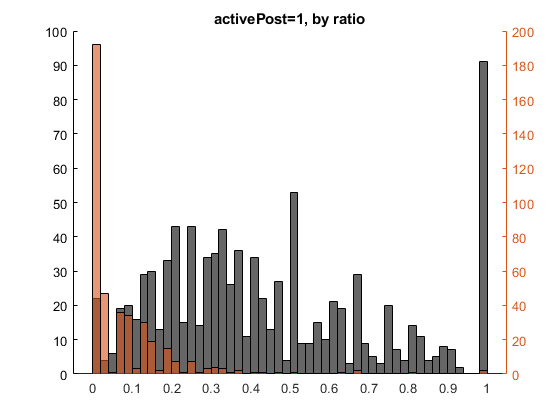

% Running backwards, can choose loose criterion, such as >0.1, only ada a few tens of false positives? 
% Running forwards, can choose strict criterion, such as >0.3, to eliminate >5000 false positives? 
ind = (T.cStrainRank>0)&(T.cTrueTwin==1)&(T.activePost==1);   % twinned --> try add these based on post
t1 = T(ind,:);
ind = (T.cStrainRank>0)&(T.cTrueTwin==0)&(T.activePost==1);   % not twinned -> try do not add these based on post
t2 = T(ind,:);
t1CS = cumsum([t1.d1, t1.d2, t1.d3, t1.d4, t1.d5],2);
t2CS = cumsum([t2.d1, t2.d2, t2.d3, t2.d4, t2.d5],2);

figure; hold on;
histogram(t1CS(:,5)./t1.nPeaks,50);
yyaxis right;
histogram(t2CS(:,5)./t2.nPeaks,50);
title('activePost=1, by ratio');   

% This simulate if we have gone back, set th=0.1, then ~60 false positives will be added.  



disp('====simulate selection====');

====simulate selection====


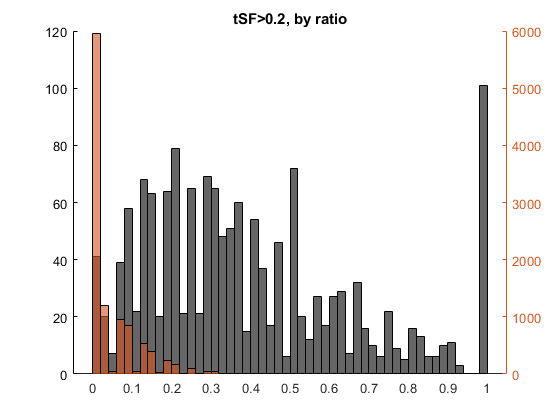

 
th_fwd = 0.35;
tSF_th = 0.2;   % min twin SF considered

% Look at those with SF>0.1
ind = (T.cStrainRank>0)&(T.cTrueTwin==1)&(T.tSF>tSF_th);   % twinned
t1 = T(ind,:);
ind = (T.cStrainRank>0)&(T.cTrueTwin==0)&(T.tSF>tSF_th);   % not twinned
t2 = T(ind,:);
t1CS = cumsum([t1.d1, t1.d2, t1.d3, t1.d4, t1.d5],2);
t2CS = cumsum([t2.d1, t2.d2, t2.d3, t2.d4, t2.d5],2);

figure; hold on;
histogram(t1CS(:,5)./t1.nPeaks,50);
yyaxis right;
histogram(t2CS(:,5)./t2.nPeaks,50);
title(['tSF>',num2str(tSF_th),', by ratio']);

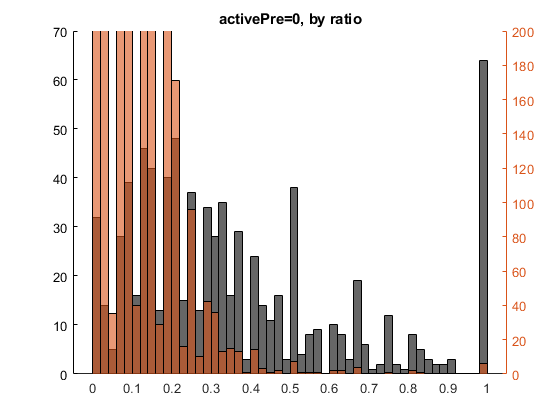



% The following is activePre=0, i.e., first identify to be twinned, need a more strict criterion.  
ind = (T.cStrainRank>0)&(T.cTrueTwin==1)&(T.tSF>tSF_th)&(T.activePre==0);
t1 = T(ind,:);
ind = (T.cStrainRank>0)&(T.cTrueTwin==0)&(T.tSF>tSF_th)&(T.activePre==0);   % all the real non-twinned
t2 = T(ind,:);
t1CS = cumsum([t1.d1, t1.d2, t1.d3, t1.d4, t1.d5],2);
t2CS = cumsum([t2.d1, t2.d2, t2.d3, t2.d4, t2.d5],2);

figure; hold on;
histogram(t1CS(:,5)./t1.nPeaks,50);
yyaxis right;
histogram(t2CS(:,5)./t2.nPeaks,50);
set(gca,'ylim',[0 200]);
title('activePre=0, by ratio');

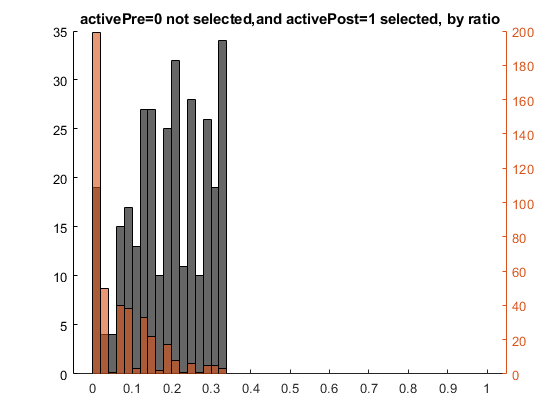

% This simulate if we set th=0.35, then ~60 false positives will be added  


% The next step is: for those not selected during forward run,  how many will be selected later    
TCS = cumsum([T.d1, T.d2, T.d3, T.d4, T.d5],2);
ind = (T.cTrueTwin==1)&(T.activePre==0)&(T.activePost==1)&(TCS(:,5)./T.nPeaks<th_fwd)&(T.tSF>tSF_th);
t1 = T(ind,:);
ind = (T.cTrueTwin==0)&(T.activePre==0)&(T.activePost==1)&(TCS(:,5)./T.nPeaks<th_fwd)&(T.tSF>tSF_th);
t2 = T(ind,:);
t1CS = cumsum([t1.d1, t1.d2, t1.d3, t1.d4, t1.d5],2);
t2CS = cumsum([t2.d1, t2.d2, t2.d3, t2.d4, t2.d5],2);

figure; hold on;
histogram(t1CS(:,5)./t1.nPeaks, 0:0.02:th_fwd);
yyaxis right;
histogram(t2CS(:,5)./t2.nPeaks, 0:0.02:th_fwd);
set(gca,'ylim',[0 200],'xlim',[-0.05 1.05]);
title('activePre=0 not selected,and activePost=1 selected, by ratio');

disp('====simulate selection, weight by tSF, not good====');

====simulate selection, weight by tSF, not good====


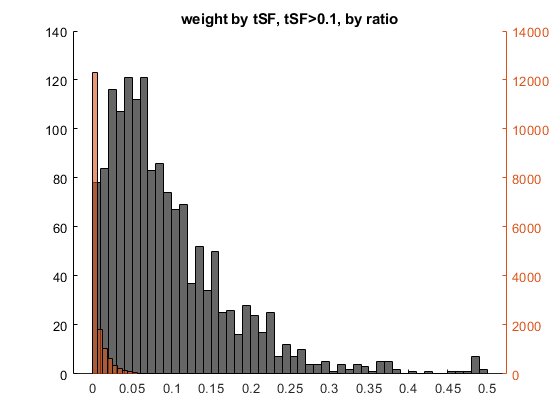

 
th_fwd = 0.6;
tSF_th = 0.1;   % min twin SF considered

% Look at those with SF>0.1
ind = (T.cStrainRank>0)&(T.cTrueTwin==1)&(T.tSF>tSF_th);   % twinned
t1 = T(ind,:);
ind = (T.cStrainRank>0)&(T.cTrueTwin==0)&(T.tSF>tSF_th);   % not twinned
t2 = T(ind,:);
t1CS = cumsum([t1.d1, t1.d2, t1.d3, t1.d4, t1.d5].*t1.tSF./[1:5],2);
t2CS = cumsum([t2.d1, t2.d2, t2.d3, t2.d4, t2.d5].*t2.tSF./[1:5],2);

figure; hold on;
histogram(t1CS(:,5)./t1.nPeaks,50);
yyaxis right;
histogram(t2CS(:,5)./t2.nPeaks,50);
title(['weight by tSF, tSF>',num2str(tSF_th),', by ratio']);

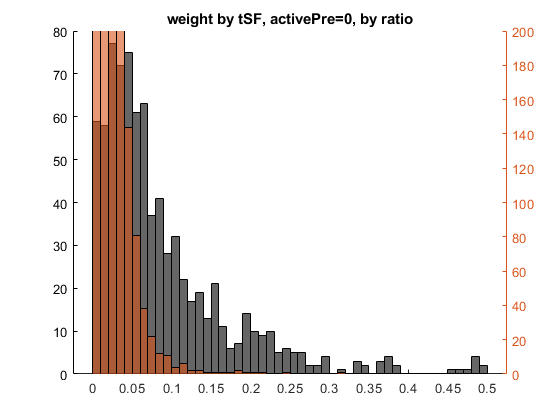




% The following is activePre=0, i.e., first identify to be twinned, need a more strict criterion.  
ind = (T.cStrainRank>0)&(T.cTrueTwin==1)&(T.tSF>tSF_th)&(T.activePre==0);
t1 = T(ind,:);
ind = (T.cStrainRank>0)&(T.cTrueTwin==0)&(T.tSF>tSF_th)&(T.activePre==0);   % all the real non-twinned
t2 = T(ind,:);
t1CS = cumsum([t1.d1, t1.d2, t1.d3, t1.d4, t1.d5].*t1.tSF./[1:5],2);
t2CS = cumsum([t2.d1, t2.d2, t2.d3, t2.d4, t2.d5].*t2.tSF./[1:5],2);


% This simulate if we set th=0.35, then ~60 false positives will be added  
figure; hold on;
histogram(t1CS(:,5)./t1.nPeaks,0:0.01:0.5);
yyaxis right;
histogram(t2CS(:,5)./t2.nPeaks,0:0.01:0.5);
set(gca,'ylim',[0 200]);
title('weight by tSF, activePre=0, by ratio');

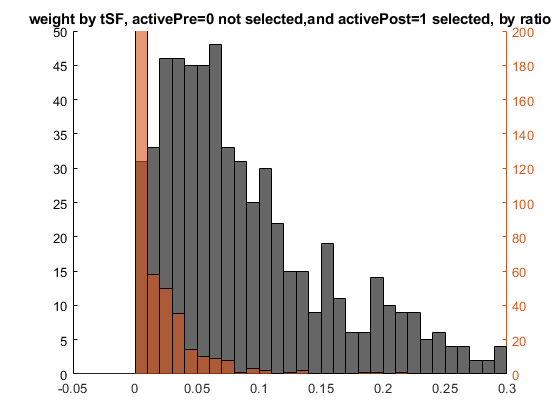





% The next step is: for those not selected during forward run,  how many will be selected later    
TCS = cumsum([T.d1, T.d2, T.d3, T.d4, T.d5].*T.tSF./[1:5],2);
ind = (T.cTrueTwin==1)&(T.activePre==0)&(T.activePost==1)&(TCS(:,5)./T.nPeaks<th_fwd)&(T.tSF>tSF_th);
t1 = T(ind,:);
ind = (T.cTrueTwin==0)&(T.activePre==0)&(T.activePost==1)&(TCS(:,5)./T.nPeaks<th_fwd)&(T.tSF>tSF_th);
t2 = T(ind,:);
t1CS = cumsum([t1.d1, t1.d2, t1.d3, t1.d4, t1.d5].*t1.tSF./[1:5],2);
t2CS = cumsum([t2.d1, t2.d2, t2.d3, t2.d4, t2.d5].*t2.tSF./[1:5],2);

figure; disableDefaultInteractivity(gca); hold on;
histogram(t1CS(:,5)./t1.nPeaks, 0:0.01:th_fwd);
yyaxis right;
histogram(t2CS(:,5)./t2.nPeaks, 0:0.01:th_fwd);
set(gca,'ylim',[0 200],'xlim',[-0.05 0.3]);
title('weight by tSF, activePre=0 not selected,and activePost=1 selected, by ratio');

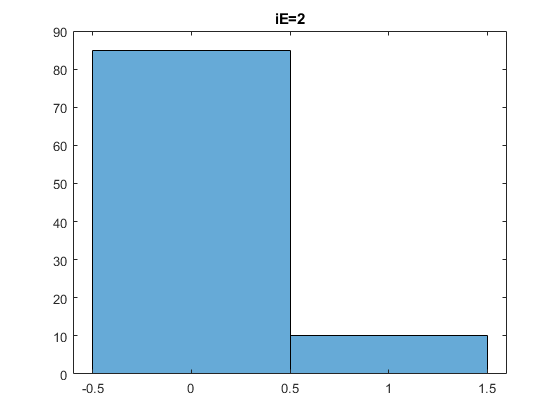

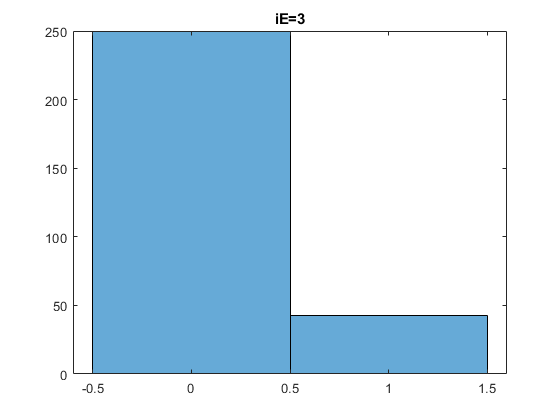

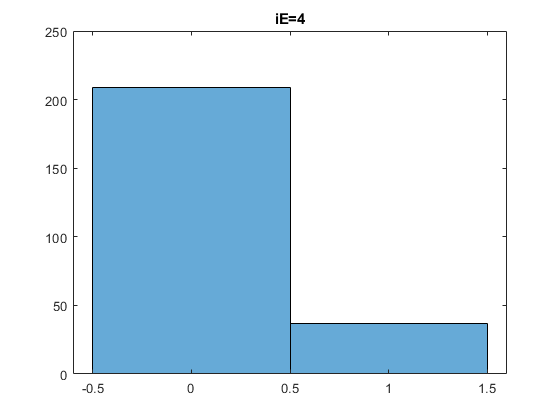

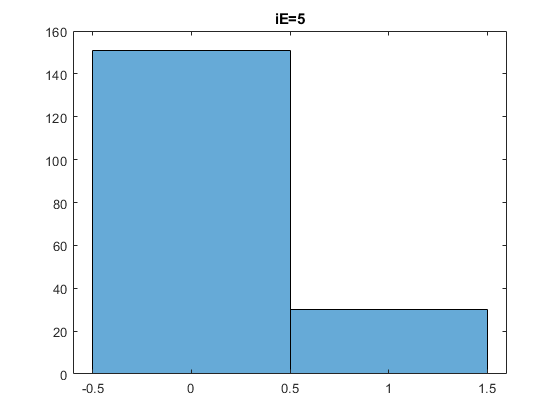

% For active twins, how many have non-twin theoretical traces 
for iE=2:5
    ind = (T.iE==iE)&(T.cStrainRank>0)&(T.cTrueTwin==1)&(T.tSF>tSF_th)&(T.activePre==0);
    t1 = T(ind,:);
    figure;
    histogram(t1.nd5);  % -> # of other twin systems with theoretical trace direction within 5d to its twin trace dir
    title(['iE=',num2str(iE)]);
end